## iterational blind deconvolution

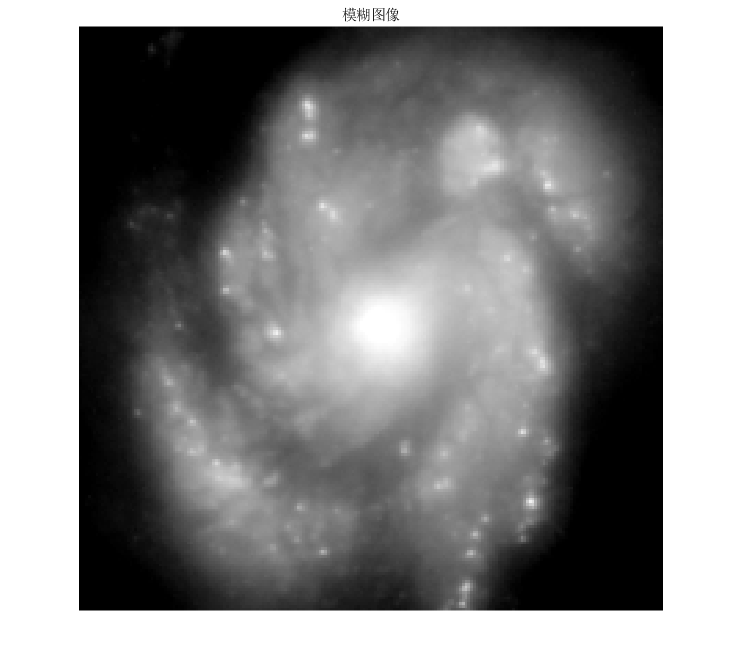

% 迭代盲反卷积图像恢复
clear all,close all,clc;
warning off
imgColor = imread('HW4.tif');
img = im2double(rgb2gray(imgColor));
figure,imshow(img),title('模糊图像');

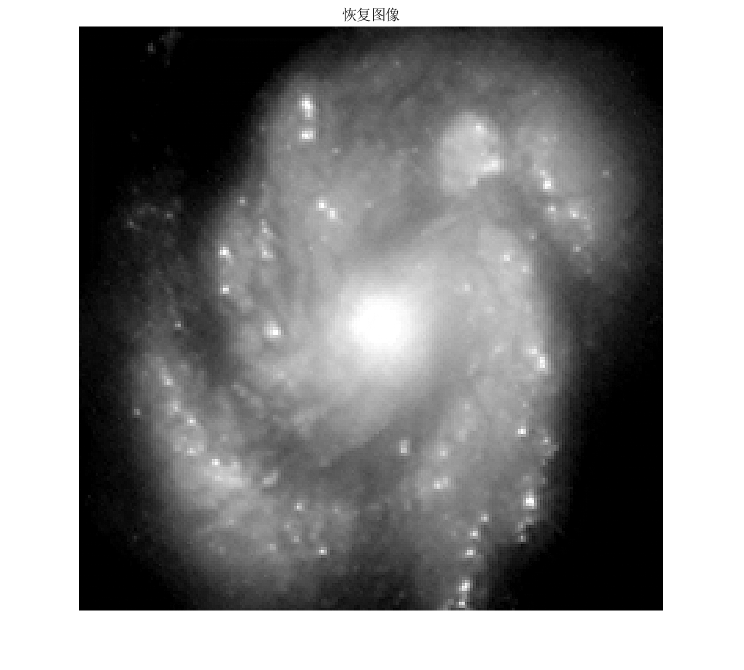

area = prod(size(img));

size_psf = 15;
wpsf = zeros(size(img));
wpsf(1:size_psf,1:size_psf) = 1; % PSF支撑域

iterTime = 20;
fw = img; % 图像初值
beta = .8; % 迭代参数
noiseLevel = 1;
C = fft2(img);
Gw = zeros(size(C)); % PSF频谱初值

for p = 1:iterTime
	Fw = fft2(fw);
	G = getEstimateSpec(C,Fw,Gw,beta,noiseLevel); % 得到新的PSF频谱估计值
	g = real(ifft2(G));
	gw = g; gw(gw < 0) = 0; % 空域约束
	gw = gw.*wpsf; % 支撑域
	gw = gw/sum(gw(:)); % 能量约束
	Gw = fft2(gw);
	
	F = getEstimateSpec(C,Gw,Fw,beta,noiseLevel);
	f = real(ifft2(F));
	fw = f; fw(fw < 0) = 0;
	E = sum(abs(fw(:)-f(:)));
	fw = fw+E/area; % 能量补充
end

figure,imshow(fw),title('恢复图像');

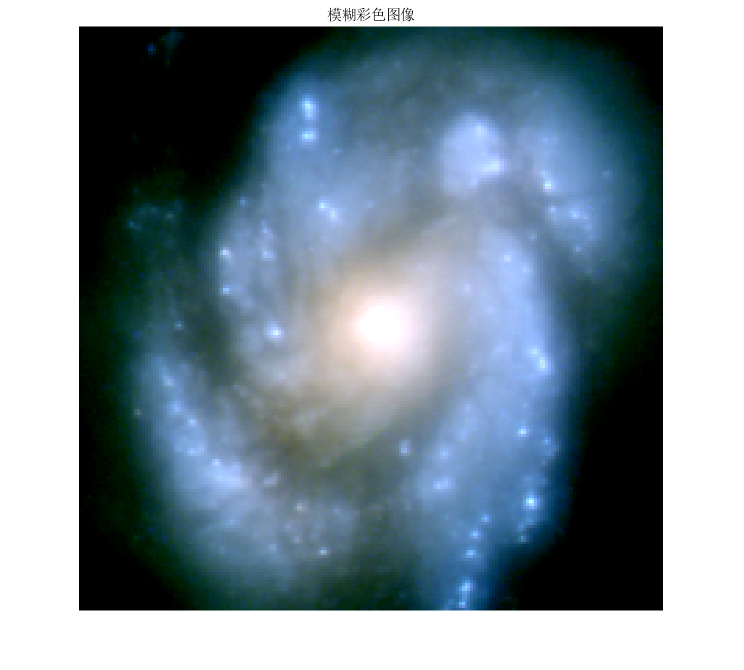

img(img == 0) = 1; % 防止除数为0
for p = 1:3
	fwColor(:,:,p) = im2double(imgColor(:,:,p)).*(fw./img); % 彩色恢复图像近似
end
figure,imshow(imgColor),title('模糊彩色图像');

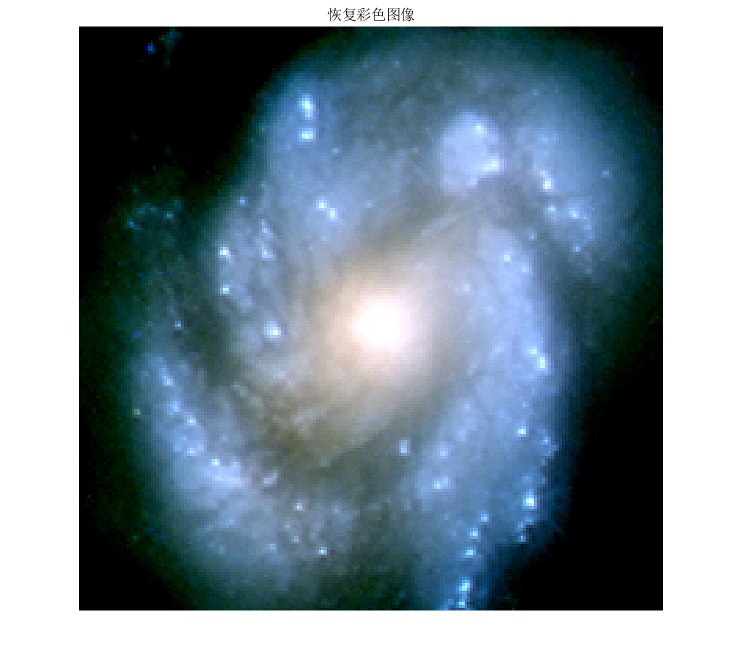

figure,imshow(fwColor),title('恢复彩色图像');

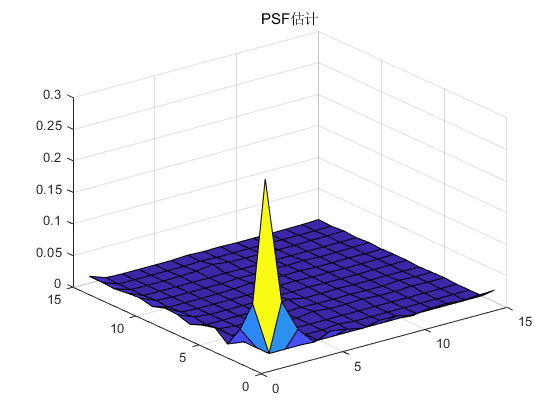


figure,surf(gw(1:size_psf,1:size_psf)),title('PSF估计');

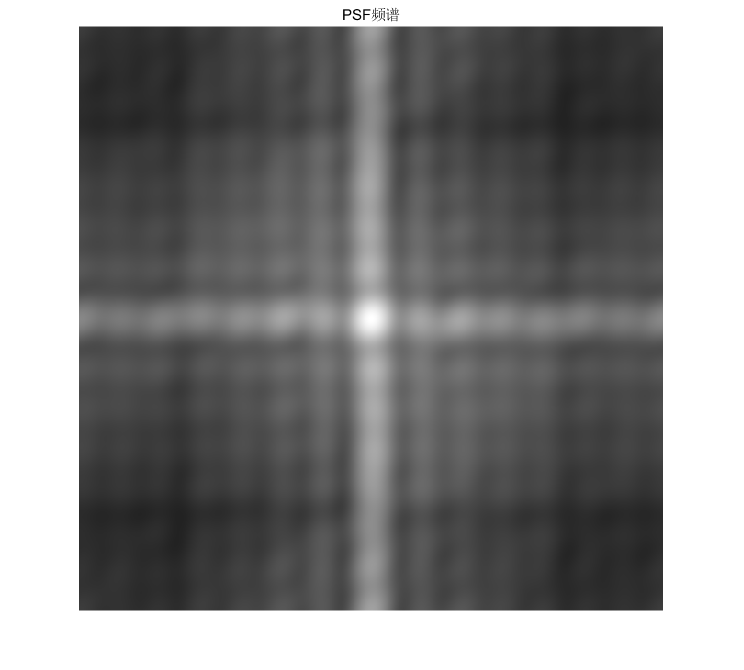

figure,imshow(fftshift(abs(Gw))),title('PSF频谱');